# Assignment 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Just warm up by computing the ES of the location
%    scale Student t, and comparing analytic and
%    numeric integration.

% Set the tail prob alpha, and the Student t degrees
%    of freedom df, then calculate the left tail quantile
%    of the location 0, scale 1 distribution.

% alpha is the probabiltu
% degree of freedom is 5
alpha=0.01; df=4; 
%c01 is the x at cdf(x)
c01=tinv(alpha , df); 
al=tcdf(c01,df);



% location zero, scale 1 ES for student t, calculating it
%   using first the analytic exact expression: 

% tpdf returns the pdf at x
% tcdf returns the cdf at x
ES_01_analytic = -tpdf(c01,df)/tcdf(c01,df) * (df+c01^2)/(df-1)

ES_01_analytic = -5.2206

% and now numeric integration:
I01 = @(x) x.*tpdf(x, df);
ES_01_numint = integral(I01 , -Inf , c01) / alpha

ES_01_numint = -5.2206

% they agree to about 14 digits!

% now incorporate location and scale and check analytic vs numint
loc=1; scale=2; cLS = loc+scale*c01; % cLS is cutoff Location Scale 
ES_wLS_analytic = loc+scale*ES_01_analytic

ES_wLS_analytic = -9.4412

ILS = @(y) (y).*tpdf((y-loc)/scale, df)/scale;
ES_wLS_numint = integral(ILS , -Inf , cLS) / alpha

ES_wLS_numint = -9.4412

% again, perfect agreement. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Inspect true ES versus simulation for a small sample size

% obtain the true ES, unknown in real life
loc=1; scale=2; df=4; alpha=0.01; % possibly new parameters
c01 = tinv(alpha , df); % left tail quantile, for loc-0 scale-1
truec = loc+scale*c01; % left tail quantile c
ES01 = -tpdf(c01,df)/tcdf(c01,df) * (df+c01^2)/(df-1);
trueES = loc+scale*ES01 % true theoretical ES

trueES = -9.4412

% simulate T-length vectors of IID location scale student t data
%   and record the empirical ES, and then compare to true
T=1e4; 
rep=200; 
ESvec=zeros(rep,1);
for i=1:rep
  data=loc+scale*trnd(df,T,1); 
  VaR=quantile(data,alpha); 
  temp=data(data<=VaR); 
  ESvec(i)=mean(temp);
end

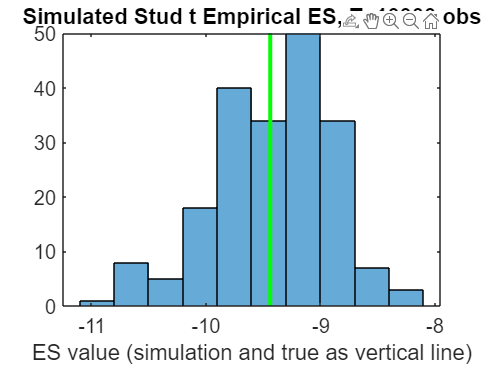

% Now make a nice, visually appealing graphic:
figure
histogram(ESvec)
ax=axis;
set(gca,'fontsize',15)
line ([ trueES trueES ] ,[0 ax(4)], 'color', 'g ', 'linewidth',3)
xlabel('ES value (simulation and true as vertical line)')
title(['Simulated Stud t Empirical ES, T=',int2str(T),' obs'])